% Set session name
session = "20230124_115956__CHS030_B4_APOP_control";

% Set video names
name_video_1 = "CHS030_B4_2023-01-24-12-00-34_cam_1";
name_video_2 = "CHS030_B4_2023-01-24-12-00-34_cam_2";

% Read videos
filename_video1 = "Z:\Behavioural_data\EyeCam\"+name_video_1+".mp4";
filename_video2 = "Z:\Behavioural_data\EyeCam\"+name_video_2+".mp4";
video1 = VideoReader(filename_video1);
video2 = VideoReader(filename_video2);

% Extract only one value from the RGB
video1 = read(video1);
video1 = squeeze(video1(:, :, 1, :));
video2 = read(video2);
video2 = squeeze(video2(:, :, 1, :));

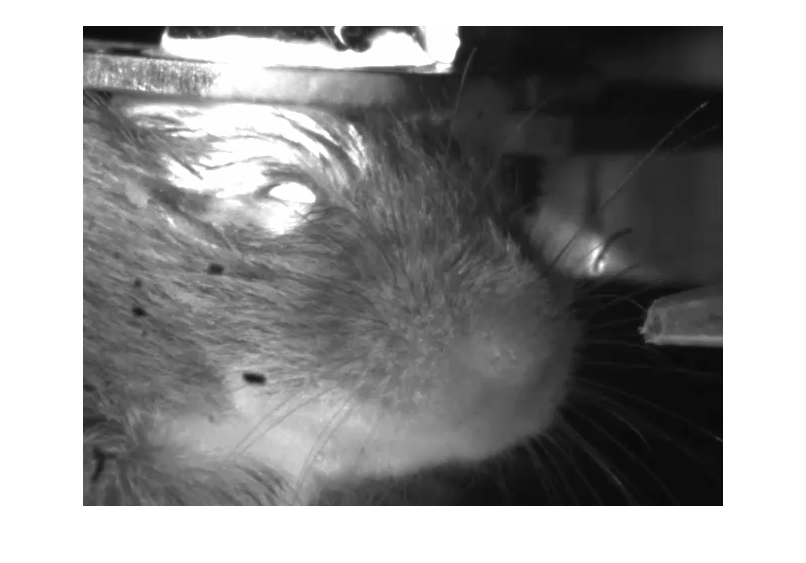

% Get coordinates for video 1
imshow(video1(:, :, 1));
[x1, y1] = ginput(1);

close;
x1 = fix(x1);
y1 = fix(y1);

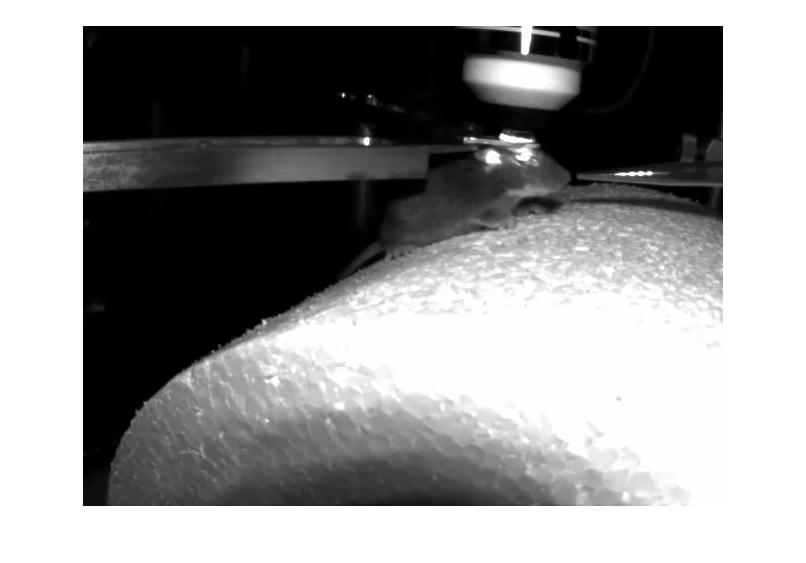

% Get coordinates for video 2
imshow(video2(:, :, 1));
[x2, y2] = ginput(1);

close;
x2 = fix(x2);
y2 = fix(y2);

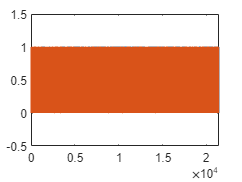

% Synchronise
[p1, p2, zero_indices_p1, zero_indices_p2] = create_P(video1, video2, x1, x2, y1, y2);

Expected irregularity at frame 449
Expected irregularity at frame 563
Expected irregularity at frame 968
Expected irregularity at frame 1059
Expected irregularity at frame 1361
Expected irregularity at frame 1505
Expected irregularity at frame 2544


Error: unexpected error at frame 2925


Video 2 missed a frame 2931


Video 1 missed a frame 3080
Video 1 missed a frame 3352
Video 1 missed a frame 3431


Video 2 missed a frame 3563
Video 2 missed a frame 3575


Video 1 missed a frame 3616


Video 2 missed a frame 4058


Video 1 missed a frame 4420


Expected irregularity at frame 4710
Expected irregularity at frame 4716
Expected irregularity at frame 4722
Expected irregularity at frame 4728


Video 2 missed a frame 4765
Video 2 missed a frame 4886
Video 2 missed a frame 5013
Video 2 missed a frame 5382
Video 2 missed a frame 5509
Video 2 missed a frame 5642
Video 2 missed a frame 6264


Error: unexpected error at frame 6620


Video 2 missed a frame 6626
Video 2 missed a frame 7110


Expected irregularity at frame 7284


Video 1 missed a frame 7446


Video 2 missed a frame 7629


Video 1 missed a frame 8025
Video 1 missed a frame 9137


Error: unexpected error at frame 9349


Video 2 missed a frame 9355
Video 2 missed a frame 9452
Video 2 missed a frame 9696


Video 1 missed a frame 9943
Video 1 missed a frame 11049


Video 2 missed a frame 11219
Video 2 missed a frame 11473


Video 1 missed a frame 11713


Expected irregularity at frame 12051


Video 2 missed a frame 12547


Expected irregularity at frame 12776
Expected irregularity at frame 12782
Expected irregularity at frame 12788
Expected irregularity at frame 12794


Video 1 missed a frame 12853
Video 1 missed a frame 13144
Video 1 missed a frame 13222


Video 2 missed a frame 13665


Error: unexpected error at frame 13925


Video 2 missed a frame 13931
Video 2 missed a frame 15562
Video 2 missed a frame 16367
Video 2 missed a frame 16385


Video 1 missed a frame 16547


Error: unexpected error at frame 16784


Video 2 missed a frame 16790
Video 2 missed a frame 16934
Video 2 missed a frame 17279


Video 1 missed a frame 17956


Expected irregularity at frame 17999


Video 2 missed a frame 18379
Video 2 missed a frame 18446


Video 1 missed a frame 18475
Video 1 missed a frame 18953


Video 2 missed a frame 19129
Video 2 missed a frame 19582
Video 2 missed a frame 19709


Expected irregularity at frame 19926


Video 1 missed a frame 20294


Video 2 missed a frame 20416


Video 1 missed a frame 20632


Video 2 missed a frame 20814
Video 2 missed a frame 20971
Video 2 missed a frame 21326
Video 2 missed a frame 21399


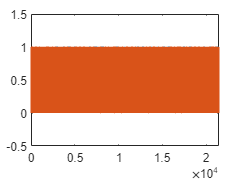

for i = 1:length(p1)
    if p1(i)==0 % focus on checking when the frame doesn't have light which is more consistent and easier to compare, especially during irregularities 
        if p1(i)==p2(i)
            continue
        else
            if (i+25)>length(p1)
                disp("There aren't enough frames to check synchronicity")
                % Here you check the final number of frames of each video
                % and you add the necessary frames to match since it's not
                % possible to know if it is just expected irregularity or
                % frame loss.
                continue
            else
                a_p1 = find(zero_indices_p1 > i & zero_indices_p1 <= i+25); %gets the indices of the list of indices which meet the conditions
                s_p1 = zero_indices_p1(a_p1); % gets the values of the list of indices
                a_p2 = find(zero_indices_p2 > i & zero_indices_p2 <= i+25); %gets the indices of the list of indices which meet the conditions
                s_p2 = zero_indices_p2(a_p2); % gets the values of the list of indices
                if any(p1(s_p1)==p2(s_p2)) % checks if any following zeros match
                    disp("Expected irregularity at frame "+ i)
                    % This is when the camera and the light misalign
                    % probably because the cameras have a frequency of 30.2HZ.
                    % This area should be ignored.
                    continue
                else
                    if p1(i) == p2(i+1)
                        disp("Video 1 missed a frame "+ i)
                        % Create new frame by averaging curent and following frame
                        new_frame = (video1(:,:,i)+video1(:,:,i+1))/2;
                        % Insert frame in the video1
                        video1 = cat(3, video1(:,:, 1:i), new_frame, video1(:,:,i+1:end));
                        % Replot everything and repeat the code from where
                        % p is introduced
                        [p1, p2, zero_indices_p1, zero_indices_p2] = create_P(video1, video2, x1, x2, y1, y2);
                        continue
                    elseif p1(i) == p2(i-1)
                        disp("Video 2 missed a frame " + i)
                         % Create new frame by averaging curent and following frame
                        new_frame = (video2(:,:,i)+video2(:,:,i+1))/2;
                        % Insert frame in the video1
                        video2 = cat(3, video2(:,:, 1:i), new_frame, video2(:,:,i+1:end));
                        % Replot everything and repeat the code from where
                        % p is introduced
                        [p1, p2, zero_indices_p1, zero_indices_p2] = create_P(video1, video2, x1, x2, y1, y2);
                        continue
                    elseif p1(i) == p2(i+2)
                        error("Error: Video 1 missed 2 frames " + i)
                        % This would be unexpected
                        continue
                    elseif p1(i) == p2(i-2)
                        error("Error: Video 2 missed 2 frames " + i)
                        % This would be unexpected
                        continue
                    else
                        error("Error: unexpected error at frame " + i)
                        % Should investigate what happened and potentially
                        % redo the session with different parameters (for
                        % example different coordinates selected)
                        continue
                    end
                end
            end
        end
    else
        continue
    end
end

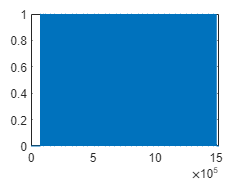

% Check the video frames

% Get the appropriate .bin file and open it
path = '\\RS-C\Khan Group\Data\Filipe\CHS\';
name = erase(extractBetween(name_video_1, 11, 20), "-") + "*" + extractBetween(name_video_1, 1, 9);
file = uigetfile(fullfile(path, name+"*.bin"));

% Convert to character array for readAIrecorderBinFile
filepath = char(path + "" + file);

% Open the .bin file
bin = readAIrecorderBinFile(filepath);

% Get the bin frames
bin_frames = bin.data(:, 14);

% Create a binary plot
for i = 1:length(bin_frames)
    if bin_frames(i, :) > 3500
        bin_frames(i, :) = 1;
    else
        bin_frames(i, :) = 0;
    end
end

figure; plot(bin_frames);


% Count the number of peaks
diff_array = diff(bin_frames);
count = sum(diff_array == 1);


% Check if the videos frames match between them
if all(size(video1, 3) == size(video2, 3)) && size(video2, 3) == count
    % do nothing
else
    error("Error: The video frames are not correct")
end

Error: The video frames are not correct

%% Save the spikes and video triggers
% Get spikes triggers
spikes_triggers = bin.data(:, 1);

% Get video triggers
video_triggers = bin.data(:, 14);

save("Z:\Behavioural_data\EyeCam\Preprocessed\"+session+"\spikes_triggers", "spikes_triggers")
save("Z:\Behavioural_data\EyeCam\Preprocessed\"+session+"\video_triggers", "video_triggers")

% % Save new videos
% % Create a VideoWriter object
% new_video1 = VideoWriter("Z:\Behavioural_data\EyeCam\Preprocessed\"+name_video_1+".avi");
% 
% % Open the video writer and write each frame to the video
% open(new_video1);
% for i = 1:length(video1)
%     frame = video1(:,:,i);
%     writeVideo(new_video1, frame);
% end
% 
% % Close the video writer
% close(new_video1);
% 
% new_video2 = VideoWriter("Z:\Behavioural_data\EyeCam\Preprocessed\"+name_video_2+".avi");
% 
% % Open the video writer and write each frame to the video
% open(new_video2);
% for i = 1:length(video2)
%     frame = video2(:,:,i);
%     writeVideo(new_video2, frame);
% end
% 
% % Close the video writer
% close(new_video2);

% This code saves the file as numpy instead of avi
% Import numpy module
numpy = py.importlib.import_module("numpy");

% Convert to numpy array
numpy_video1 = py.numpy.array(video1);

% Save numpy_video to file
py.numpy.save("Z:\Behavioural_data\EyeCam\Preprocessed\"+session+"\"+name_video_1+".npy", numpy_video1);

% Convert to numpy array
numpy_video2 = py.numpy.array(video2);

% Save numpy_video to file
py.numpy.save("Z:\Behavioural_data\EyeCam\Preprocessed\"+session+"\"+name_video_2+".npy", numpy_video2);

function [p1, p2, zero_indices_p1, zero_indices_p2] = create_P(video1, video2, x1, x2, y1, y2)
    
    % Crop rectangle and average intensity of pixels
    p1 = single(video1(y1:(y1+15),x1:(x1+15),:));
    p2 = single(video2(y2:(y2+10),x2:(x2+10),:));
    p1 = squeeze(max(p1, [], [1 2]));
    p2 = squeeze(max(p2, [], [1 2]));
    
    % Create a binary graph
    for i = 1:length(p1)
        if p1(i,:)>220
            p1(i,:)=1;
        else
            p1(i, :)=0;
        end
    end
    
    for i = 1:length(p2)
        if p2(i,:)>230
            p2(i,:)=1;
        else
            p2(i,:)=0;
        end
    end

    % Plot the binary graph
    plot(p1)
    hold on
    plot(p2)
    ylim([-0.5 1.5])
    hold off
    
    % List indices when light is off
    zero_indices_p1 = single(find(p1 == 0));
    zero_indices_p2 = single(find(p1 == 0));

end